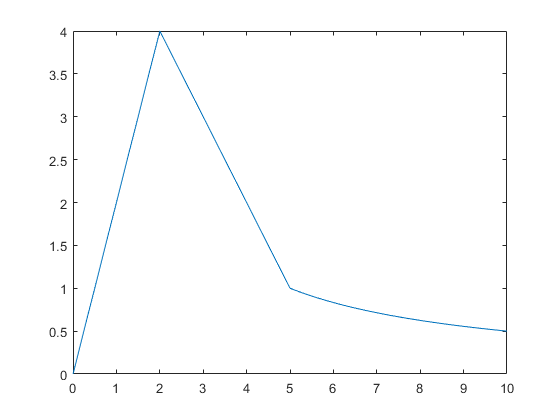

syms t x;

lim = [0,2,5,10];
fx = [ 2*t; 6-t ; 5/t   ];
n = 51;

tt = linspace(lim(1),lim(end),n)';
xx = zeros(n,1);


num = length(lim) - 1;
s = zeros(num,1);

judge = 2;
for i = 1:n
    if tt(i) > lim(judge)
        judge = judge +1;
    end
    ft(t) = fx(judge-1); 
    xx(i) = ft(tt(i));   
end



plot(tt,xx)


n = 11;

tt = linspace(-1,1,n);

r = zeros(n,1);

for i = 1:n
    r(i) = fenduan(tt(i));
end

plot(tt,r)




function m = fenduan(t)
m = 1+t.*(t>=0);

end